# 1 DOF Cell Model in plane strain

## Data

clear all; close all; clc;
set_env;
addpath("Functions and Scripts\");
addpath("1DOF\");

% Data --------------------------------------------------------------
% Constants
eps_0 = 8.85e-12; 			% F/m , permittivity of vacuum
epsilon1_max = 0.05;

pstrain = "PSTRAIN";
% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F(x,V) C(x)
% 
% % Strains: eps1 along the polymer, eps3 thickness strain of the polymer

syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)


## Equations

syms eps1 eps2 eps3 s1 s2 s3   
% Equations ---------------------------------------------------------
eqstrain = [
eps1 == 1 / Y_p * (s1 - nu * (s2 + s3)),...
eps2 == 1 / Y_p * (s2 - nu * (s1 + s3)),...
eps3 == 1 / Y_p * (s3 - nu * (s1 + s2))
]

$$eqstrain = \left(\begin{array}{ccc} {\mathrm{eps}}_{1}=\frac{s_{1}-\nu \,\left(s_{2}+s_{3}\right)}{Y_{p}} & {\mathrm{eps}}_{2}=\frac{s_{2}-\nu \,\left(s_{1}+s_{3}\right)}{Y_{p}} & {\mathrm{eps}}_{3}=\frac{s_{3}-\nu \,\left(s_{1}+s_{2}\right)}{Y_{p}} \end{array}\right)$$


% Plane strain: eps2 = 0 and s3 = 0
soldef = solve(subs(eqstrain, {eps2,s3}, {0,0}), [s1, s2, eps3])

soldef = struct with fields:
      s1: -(Y_p*eps1)/(nu^2 - 1)
      s2: -(Y_p*eps1*nu)/(nu^2 - 1)
    eps3: (eps1*nu)/(nu - 1)


sstrain1(sigma_1)

$$ans(x) = -\frac{Y_{p}\,\left(\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}-1\right)}{\nu^{2}-1}$$



clear eps1 eps2 eps3 s1 s2 s3


% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f;

p_strain = compute_geometry(t_f, "PSTRAIN")

p_strain = struct with fields:
      l: l_0*(epsilon_1(x) + 1)
    t_p: tp_0*(epsilon_3(x) + 1)
      w: w_0
      A: l_0*w_0*(epsilon_1(x) + 1)
     dC: [1×1 symfun]
      C: [1×1 symfun]


l = p_strain.l;
t_p = p_strain.t_p;
w = p_strain.w;
A = l * w;

% Range limit
x_min = sdata1(tf_0)

$$x\_min = \frac{1}{10000}$$

x_max = sdata1(rhs(isolate(sstrain1(epsilon_1(x)) == epsilon1_max, x)))

$$x\_max = \frac{\sqrt{41}}{400}+\frac{1}{10000}$$



dA = w * (1 + epsilon_1(x)) ; % * dxi

% Polymer infinitesimal capacitance
dCp = dA * epsilon_p / t_p

$$dCp = \frac{\epsilon_{p}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}$$

% Fluid infinitesimal capacitance
dCf = dA * epsilon_f / t_f

$$dCf(x) = \frac{\epsilon_{f}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}}$$


% Total infinitesimal capacitance
dC = ((2 / dCp) + (1 / dCf))^(-1)

$$dC(x) = \frac{1}{\frac{{\mathrm{tf}}_{0}-\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}}{\epsilon_{f}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}}$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C(x) = int(dC, xi)

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}$$

C(x) = subs(C(x), xi, xi_0 + l_0) - subs(C(x), xi, xi_0)

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}$$

CC(x) = sstrain1(C, pstrain);
Cplane = simplify(limit(CC, x, tf_0))

$$Cplane = \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}}$$

C(x) = piecewise(x <= tf_0+1e-10, Cplane, x > tf_0+1e-10, CC(x))

$$C(x) = \left\{ \begin{array}{cl} \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}} & \text{ if }x\leq {\mathrm{tf}}_{0}+\frac{1}{10000000000}\\ \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\frac{2\,\epsilon_{f}\,l_{0}\,\nu \,{\mathrm{tp}}_{0}\,\left(\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}-1\right)}{\nu -1}\right)\,\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-\frac{2\,\epsilon_{f}\,l_{0}\,\nu \,{\mathrm{tp}}_{0}\,\left(\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}-1\right)}{\nu -1}\right)\,\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}}{{\mathrm{tf}}_{0}-x} & \text{ if }{\mathrm{tf}}_{0}+\frac{1}{10000000000}<x \end{array}\right.$$


% Min capacitance
Cmin = vpa(subs(sdata1(C), x, x_max), 4)

$$Cmin(x) = 1.864e-11$$


% Max C
Cmax = vpa(sdata1(Cplane), 4)

$$Cmax = 4.276e-10$$

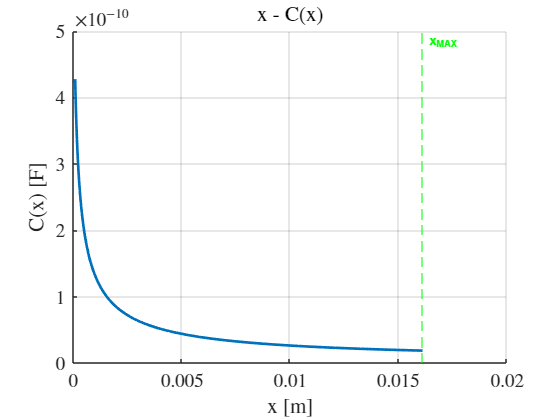

% Plot x - C(x)
myfig(1,"x - C(x)");
hold on
fplot(x, sdata1(C(x)), [double(sdata1(x_min)), double(sdata1(x_max))], 'LineWidth', 2)
xline(double(sdata1(x_max)), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontWeight','bold')
hold off
title("x - C(x)")
xlabel("x [m]")
ylabel("C(x) [F]")

## Max voltage

% Max voltage
% Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
makeassumptions
Vmax(x) = 2 * t_p / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

$$Vmax(x) = \frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\,\min\left(\left[{\mathrm{EBD}}_{f}\,\epsilon_{f},{\mathrm{EBD}}_{p}\,\epsilon_{p}\right],\left[\right],2,\text{"omitnan"},\mathrm{symfalse}\right)}{\epsilon_{p}}$$

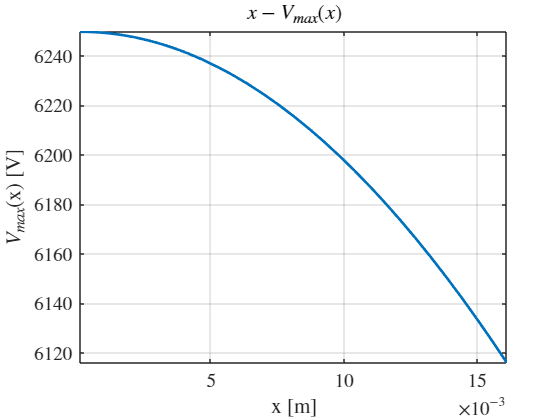


% Plot x - Vmax(x)
myfig(2,"x - Vmax(x)");
fplot(x, sdata1(Vmax(x),pstrain), [double(x_min) double(x_max)], 'LineWidth', 2)
title("$x - V_{max}(x)$")
xlabel("x [m]")
ylabel("$V_{max}$(x) [V]")

## Force

% Force
Uel(x) = 2 * sdata1(1 / 2 * (sigma_1 * epsilon_1) * w * t_p * l, pstrain)

$$Uel(x) = -\frac{15625\,\left(\frac{3\,\sqrt{400\,{\left(x-\frac{1}{10000}\right)}^{2}+1}}{7}-\frac{10}{7}\right)\,{\left(\sqrt{400\,{\left(x-\frac{1}{10000}\right)}^{2}+1}-1\right)}^{2}\,\sqrt{400\,{\left(x-\frac{1}{10000}\right)}^{2}+1}}{91}$$

F(x,V) = simplify(diff(Uel, x) - V^2 / 2 * diff(sdata1(C), x))

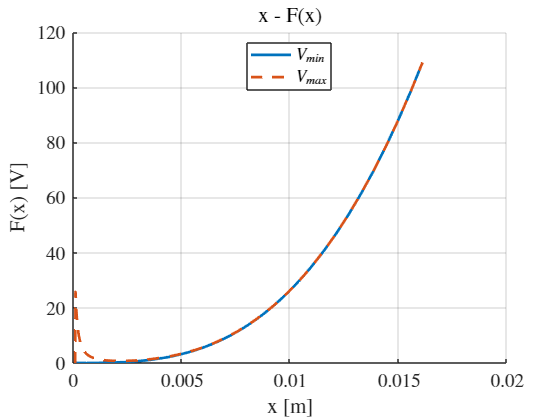


% Min and max force for V = 0 and V = Vmax
FVmin = vpa(F(x, 0), 4);
FVmax= vpa(F(x, sdata1(Vmax,pstrain)), 4);

% Plot x - F(x) 
myfig(3,"x - F(x)"); hold on
fplot(x, FVmin, [double(sdata1(x_min)), double(sdata1(x_max))], 'LineWidth', 2, 'DisplayName', '$V_{min}$')
fplot(x, real(FVmax), [double(sdata1(x_min)), double(sdata1(x_max))], '--', 'LineWidth', 2, 'DisplayName', '$V_{max}$')
title("x - F(x)")
legend("Location","north")
xlabel("x [m]")
ylabel("F(x) [V]")

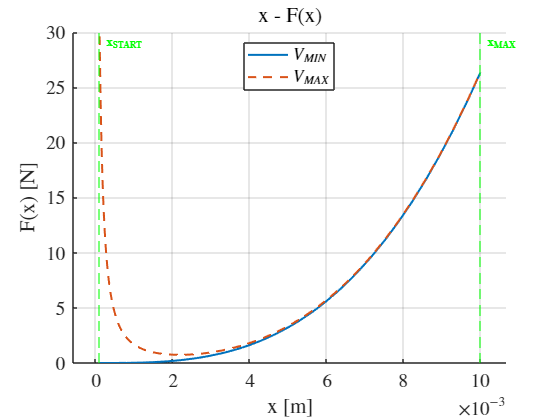

% Redefine x limits
x_range = double(x_min:1e-6:x_max);
[fvmax_peak, idx] = findpeaks(real(double(subs(FVmax, x_range))));
xstart = x_range(idx);
xend = double(min(sdata1(x_max), 0.01));


myfig(4,"x - F(x)")
hold on
fplot(x, FVmin, [xstart xend], 'LineWidth', 1.5, 'DisplayName', "$V_{MIN}$")
fplot(x, real(FVmax), [xstart xend], '--', 'LineWidth', 1.5, 'DisplayName', "$V_{MAX}$")
myxline(xstart, "--g", "x_{START}")
myxline(xend, "--g", "x_{MAX}")
hold off
legend("Location", "north")
title("x - F(x)")
xlim("padded")
xlabel("x [m]")
ylabel("F(x) [N]")

% Energy from x - F(x), use step of 2e-5
x_range = double(xstart:1e-5:xend);
FVmax_vec = double(subs(FVmax,x_range));
FVmin_vec = double(subs(FVmin,x_range));

Uel_Fx = double(trapz(x_range, FVmax_vec) - trapz(x_range, FVmin_vec))

Uel_Fx = 0.0078 - 0.0000i

## Q - V

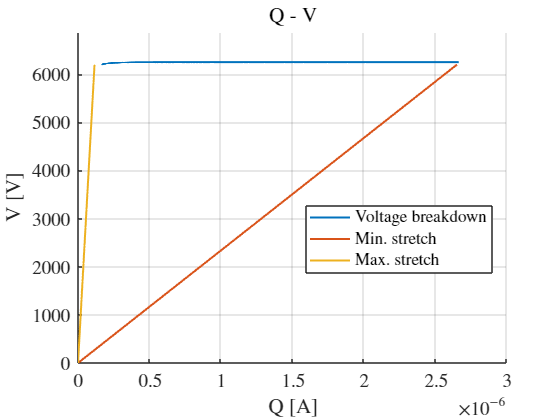

% Plot Q - V
C_vec = double(subs(sdata1(C), x, x_range));
Vmax_vec = double(subs(sdata1(Vmax, pstrain), x, x_range));
Q_vec = C_vec .* Vmax_vec;

V_vec = linspace(0, min(Vmax_vec), 100);
Qmaxstr = double(V_vec * Cmin);
Qminstr = double(V_vec * Cmax);

myfig(4,"Q - V"); clf
hold on
plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
plot(Qminstr, V_vec, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
plot(Qmaxstr, V_vec, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
legend('Location','best')
xlabel("Q [A]")
ylabel("V [V]")
ylim([0, 1.1 * max(Vmax_vec)])
title("Q - V")
hold off

% Energy from Q - V
Uel_QV = trapz(Qmaxstr, V_vec) + max(Vmax_vec) * (Qminstr(end) - Qmaxstr(end)) - trapz(Qminstr, V_vec)

Uel_QV = 0.0080

% Save results
res_1dof_pstrain.l = l;
res_1dof_pstrain.w = w;	
res_1dof_pstrain.t_p = t_p;
res_1dof_pstrain.A = A;
res_1dof_pstrain.t_f = t_f;
res_1dof_pstrain.C = C;	
res_1dof_pstrain.Vmax = Vmax;
res_1dof_pstrain.Uel = Uel;
res_1dof_pstrain.F = F;
res_1dof_pstrain.FVmin = FVmin;
res_1dof_pstrain.FVmax = real(FVmax);
res_1dof_pstrain.x_min = xstart;
res_1dof_pstrain.x_max = xend;
res_1dof_pstrain.x_range = x_range;
res_1dof_pstrain.Uel_Fx = Uel_Fx;
res_1dof_pstrain.Uel_QV = Uel_QV;
res_1dof_pstrain.Cmin = Cmin;
res_1dof_pstrain.Cmax = Cmax;
res_1dof_pstrain.Q_vec = Q_vec;
res_1dof_pstrain.V_vec = V_vec;
res_1dof_pstrain.Vmax_vec = Vmax_vec;
res_1dof_pstrain.Qmaxstr = Qmaxstr;
res_1dof_pstrain.Qminstr = Qminstr;

asksave(res_1dof_pstrain, '1DOF', '.mat')

Saved.
